## This script will generaate focused 2D clean complex data SAR data, which is used for generating attack image for MFA RMA BPA LIA

File successfully saved!

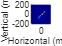

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Note: this script selects algo to generate and save complex 2D sar data
% in the current directory
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear; close all; 
sarRawData = load('rawSAR.mat').adcDataCube; % Nsamp x M x N

% --- SAR Imaging Parameters ---
c0 = physconst('lightspeed');
F0 = 77e9;        % Start frequency (Hz)
FS = 5000e3;      % Sampling rate (sps)
Ts = 1/FS;          % Sampling period
K0 = 70.295e12;   % Slope constant (Hz/sec)
tI = 4.5225e-10;  % Instrument delay (s)

nFFTtime = 1024;  % Range-FFT points
nFFTspace = 1024; % Spatial-FFT points (for MFA)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
sar_algo = 'MFA'; % Options: 'MFA', 'RMA', 'BPA', LIA
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

switch upper(sar_algo)
    case 'MFA'
        dx = 1;           % Horizontal step (mm)
        dy = 1;           % Vertical step (mm)
        bbox = [-200 200 -200 200]; % Bounding box (mm)
        %tI = 4.5225e-10;  % Instrument delay (s)
        z0 = 185;         % Target range (mm)

        % Range focusing bin index (zero-indexed range bin + 1)
        k0_range_bin = round(K0 / FS * (2 * z0 * 1e-3 / c0 + tI) * nFFTtime);

        rawDataFFT = fft(sarRawData, nFFTtime);
        sarData = squeeze(rawDataFFT(k0_range_bin + 1, :, :)); % M x N
        for ii = 2:2:size(sarData, 1)
            sarData(ii, :) = fliplr(sarData(ii, :));
        end
        
        [Nsamp, M, N] = size(sarRawData);

        % --- Parameter structure for MFA and dlarray targets ---
        params = struct('nFFTspace', nFFTspace, 'nFFTtime', nFFTtime, 'z0', z0, ...
            'dx', dx, 'dy', dy, 'bbox', bbox, 'F0', F0, 'Nsamp', Nsamp, 'N', N, 'M', M, ...
            'k0_range_bin', k0_range_bin, 'sar_algo', sar_algo);

        [~, ~, trueImage_abs, trueImage_complex] = dlMFA(sarData, params);
        sarImage = extractdata(trueImage_abs);

        %trueImage_complex = extractdata(trueImage_complex);
        
        save('trueImage_complex_MFA.mat', 'trueImage_complex');
        fprintf('File successfully saved!')

        plot_sar(sarImage, bbox, dx, dy);

        % ---- Save high-quality PDF (and optional PNG) ----
        exportgraphics(gcf, sprintf('sar_%s_figure.pdf', sar_algo), ...
            'ContentType','vector');              % vector PDF for LaTeX

        exportgraphics(gcf, sprintf('sar_%s_figure.png', sar_algo), ...
            'Resolution', 600);  

    case 'RMA'
        % [samples, vertical, horizontal]-->[horizontal, vertical, samples]
        Echo = permute(sarRawData, [3,2,1]); % rearrange adcDataCube
        dx = 1;                               % Sampling distance at x (horizontal) axis in mm
        dy = 1;                               % Sampling distance at y (vertical) axis in mm
        bbox = [-200 200 -200 200]; % Bounding box (mm)
         
        Nx = 200;                            % The sampling points in the horizontal direction
        Nz = 200;                            % The sampling points in the vertical direction
        num_sample = size(Echo,3); % 256   
        nFFTtime = num_sample;
        rawDataFFT = fft(Echo,nFFTtime,3); % 407x200x256  % Range FFT
    
        % this original one and this works---------------
        ID_select = 6; % Note: this index for knife image only    
        k0_range_bin = ID_select;
        sarData = squeeze(rawDataFFT(:,:,ID_select)).';                  % Selecting echo data after pulse compression
        z0 = c0/2*(ID_select/(K0*(1/FS)*nFFTtime) - tI);
        for ii = 2:2:Nz
            sarData(ii,:) = fliplr(sarData(ii,:));
        end
       
        [Nsamp, M, N] = size(sarRawData);
        % --- Parameter structure for RMA and dlarray targets ---
        params = struct('nFFTspace', nFFTspace, 'nFFTtime', nFFTtime, 'z0', z0, ...
            'dx', dx, 'dy', dy, 'bbox', bbox, 'F0', F0, 'Nsamp', Nsamp, 'N', N, 'M', M, ...
            'k0_range_bin', k0_range_bin, 'sar_algo', sar_algo);

        [~, ~, trueImage_abs, trueImage_complex] = dlRMA(sarData, params);
        sarImage = extractdata(trueImage_abs);
        
        save('trueImage_complex_RMA.mat', 'trueImage_complex');
        fprintf('File successfully saved!')

        plot_sar(sarImage, bbox, dx, dy);

        % ---- Save high-quality PDF (and optional PNG) ----
        exportgraphics(gcf, sprintf('sar_%s_figure.pdf', sar_algo), ...
            'ContentType','vector');              % vector PDF for LaTeX

        exportgraphics(gcf, sprintf('sar_%s_figure.png', sar_algo), ...
            'Resolution', 600);  

    case 'BPA'
        dx = 1;                               % Sampling distance at x (horizontal) axis in mm
        dy = 1;                               % Sampling distance at y (vertical) axis in mm
        bbox = [-200 200 -200 200]; % Bounding box (mm)
        %z0 = 20*1e-3;         % Target range (mm)
        z0   = 185;
        rawDataFFT = fft(sarRawData, nFFTtime);

        k0 = round(K0*Ts*(2*z0 * 1e-3/c0+tI)*nFFTtime); % corresponing range bin
        sarData = squeeze(rawDataFFT(k0+1,:,:));
        for ii = 2:2:size(sarData, 1)
            sarData(ii, :) = fliplr(sarData(ii, :));
        end

        A = 50; % Image Horizontal Pixels
        B = 50; % Image Vertical Pixels
        
        [Nsamp, M, N] = size(sarRawData);

        params = struct('z0', z0,'dx', dx, 'dy', dy, 'bbox', bbox, ...
            'Nsamp', Nsamp, 'N', N, 'M', M, 'A_bpa', A, 'B_bpa', B, 'F0', F0, 'sar_algo', sar_algo);

        H_bpa = dlBPA_H_matrix(params); 

        [~, ~, trueImage_abs, trueImage_complex] = dlBPA(sarData, params, H_bpa);

        save('trueImage_complex_BPA.mat', 'trueImage_complex');
        fprintf('File successfully saved!')

        % Optional: quick visualization (same as BPA-style plot)
        sarImage = abs(trueImage_complex);
        plot_sar_bpa(sarImage, bbox, dx, dy);

        % ---- Save high-quality PDF (and optional PNG) ----
        exportgraphics(gcf, sprintf('sar_%s_figure.pdf', sar_algo), ...
            'ContentType','vector');              % vector PDF for LaTeX

        exportgraphics(gcf, sprintf('sar_%s_figure.png', sar_algo), ...
            'Resolution', 600);  

   
case 'LIA'
        % Use same geometry as BPA so images line up
        dx   = 1;                               % mm
        dy   = 1;                               % mm
        bbox = [-200 200 -200 200];            % mm
        z0   = 185;                             % mm

        % Range FFT and slice at desired bin
        [Nsamp, N, M] = size(sarRawData);
        rawDataFFT    = fft(sarRawData, nFFTtime);
        k0_range_bin  = round(K0*Ts*(2*z0 * 1e-3/c0 + tI)*nFFTtime);
        sarData       = squeeze(rawDataFFT(k0_range_bin+1, :, :));  % M x N

        % Serpentine correction
        for ii = 2:2:size(sarData, 1)
            sarData(ii, :) = fliplr(sarData(ii, :));
        end

        % Image size (same as BPA)
        A = 50; % Horizontal pixels
        B = 50; % Vertical pixels

        % Params (reuse BPA fields so H_bpa is identical)
        params = struct('z0', z0, 'dx', dx, 'dy', dy, 'bbox', bbox, ...
            'Nsamp', Nsamp, 'N', N, 'M', M, ...
            'A_bpa', A, 'B_bpa', B, 'F0', F0, ...
            'sar_algo', sar_algo);

        % Build full H matrix once (same as BPA)
        H_bpa = dlBPA_H_matrix(params);
        params.H_bpa = H_bpa;

        % Choose sensor subset py for LIA (Li & Chen SPL)
        NM = M * N;
        kk = min(40000, NM);                  % can tune if you want
        rng(1000);                            % fixed for reproducibility
        params.py = sort(randperm(NM, kk));   % index subset

        % Run LIA imaging
        [~, ~, trueImage_abs, trueImage_complex] = dlLIA(sarData, params, H_bpa);

        % Save complex image for the attack pipeline
        save('trueImage_complex_LIA.mat', 'trueImage_complex');
        fprintf('File successfully saved!\n');

        % Optional: quick visualization (same as BPA-style plot)
        sarImage = abs(trueImage_complex);
        plot_sar_bpa(sarImage, bbox, dx, dy);

        % ---- Save high-quality PDF (and optional PNG) ----
        exportgraphics(gcf, sprintf('sar_%s_figure.pdf', sar_algo), ...
            'ContentType','vector');              % vector PDF for LaTeX

        exportgraphics(gcf, sprintf('sar_%s_figure.png', sar_algo), ...
            'Resolution', 600);  

    otherwise
        error('Invalid SAR algorithm selection.');
end

%%%%%%%%%%%%%%%%%%%%% LIA (Li & Chen iterative imaging) %%%%%%%%%%%%%%%%%%%%
function [xRangeT, yRangeT, trueImage_abs, trueImage_complex] = dlLIA(sarData, params, H_bpa)
% DLLIA: Lightweight Iterative Imaging Algorithm (LIA) using the
%        same propagation matrix H_bpa as BPA.
%
% Inputs:
%   sarData  : M x N complex slice at the chosen range bin (serpentine corrected)
%   params   : struct with fields:
%              - M, N        : aperture size
%              - A_bpa, B_bpa: image size (A x B)
%              - bbox, dx, dy, z0
%              - py          : index subset of sensor samples (length kk)
%   H_bpa    : (M*N) x (A*B) propagation matrix from dlBPA_H_matrix
%
% Outputs:
%   xRangeT, yRangeT  : spatial axes (mm)
%   trueImage_abs     : RMS-normalized magnitude image (dlarray, 'SS')
%   trueImage_complex : complex image (B x A)

    % Ensure dlarray types for AD compatibility
    if ~isa(sarData, 'dlarray')
        sarData = dlarray(sarData);
    end
    if ~isa(H_bpa, 'dlarray')
        H_bpa = dlarray(H_bpa);
    end

    M  = params.M;
    N  = params.N;
    A  = params.A_bpa;
    B  = params.B_bpa;
    py = params.py;          % index subset (kk x 1)
    bbox = params.bbox;
    dx   = params.dx;
    dy   = params.dy;

    % --- Vectorize measurements (same ordering as dlBPA_H_matrix) ---
    rd_full = reshape(sarData, [], 1);    % (M*N) x 1
    rd      = rd_full(py);                % kk x 1

    % --- Sub-sampled propagation matrix Hp (kk x BA) ---
    Hp = H_bpa(py, :);                    % kk x (A*B)
    BA = A * B;

    % --- LIA core (myalg == 6 in Li & Chen SPL paper) ---
    di = 0.01;                            % initialization constant
    G  = di * (Hp' * Hp);                 % (BA x BA)
    xd = di * (Hp' * rd);                 % (BA x 1)

    % Iterative image updating based on matrix inversion lemma
    for j = 1:BA
        Gj    = G(:, j);                  % (BA x 1)
        denom = 1 + G(j, j);
        temp  = Gj / denom;               % (BA x 1)

        xd = xd - temp * xd(j);
        G  = G  - temp * G(j, :);
    end

    % Extract diagonal of G as column vector
    diagG = G(1:BA+1:BA*BA);              % 1 x BA (row)
    diagG = reshape(diagG, [BA, 1]);      % BA x 1 (column)

    % Final scaling (element-wise)
    xd = xd ./ diagG;                     % BA x 1

    % Reshape to B x A and flip horizontally (as in BPA)
    xdi = fliplr(reshape(xd, B, A));

    % Complex image output (convert out of dlarray for saving)
    trueImage_complex = gather(extractdata(xdi));

    % RMS-normalized magnitude
    img_mag = abs(trueImage_complex);
    rms_val = sqrt(mean(img_mag(:).^2) + eps);
    trueImage_abs = dlarray(img_mag ./ rms_val, 'SS');

    % Spatial ranges (mm)
    xRangeT = bbox(1) + (0:size(trueImage_abs, 2) - 1) * dx;
    yRangeT = bbox(3) + (0:size(trueImage_abs, 1) - 1) * dy;
end


% ----------------------------->>>>> RMA

function matchedFilter = refMF(params)
% REFMF: Generates the 2D Matched Filter coefficient.
    c = physconst('lightspeed');
    x = params.dx * (-(params.nFFTspace-1)/2 : (params.nFFTspace-1)/2) * 1e-3;
    y = (params.dy * (-(params.nFFTspace-1)/2 : (params.nFFTspace-1)/2) * 1e-3).';
    z0_m = params.z0 * 1e-3;
    k = 2 * pi * params.F0 / c;
    
    % Matched Filter: exp(-j * 2 * k * R)
    matchedFilter = exp(-1i * 2 * k * sqrt(bsxfun(@plus, x.^2, y.^2) + z0_m^2));
end

function [xRangeT, yRangeT, trueImage_abs, trueImage_complx] = dlMFA(sarData, params)
% DLMFA: 2D Matched Filter Algorithm for SAR image reconstruction.
    matchedFilter = refMF(params);
    if isa(sarData,'dlarray') && ~isa(matchedFilter,'dlarray')
        matchedFilter = dlarray(matchedFilter);
    end
    
    [yPointM, xPointM] = size(sarData);
    [yPointF, xPointF] = size(matchedFilter);
    
    % 1. Equalize Dimensions with Zero Padding
    % Pad sarData to match matchedFilter size (assuming nFFTspace >= M, N)
    if (xPointF > xPointM)
        pad_x_pre = floor((xPointF - xPointM) / 2);
        pad_x_post = ceil((xPointF - xPointM) / 2);
        sarData = cat(2, zeros(yPointM, pad_x_pre, 'like', sarData), sarData, zeros(yPointM, pad_x_post, 'like', sarData));
        xPointM = xPointF; % Update size
    end
    if (yPointF > yPointM)
        pad_y_pre = floor((yPointF - yPointM) / 2);
        pad_y_post = ceil((yPointF - yPointM) / 2);
        sarData = cat(1, zeros(pad_y_pre, xPointM, 'like', sarData), sarData, zeros(pad_y_post, xPointM, 'like', sarData));
        yPointM = yPointF; % Update size
    end
    % Note: Padding matchedFilter to match sarData is omitted as sarData is padded up to nFFTspace.

    % 2. Run 2D FFT, Multiply, and 2D IFFT (Correlation)
    sarDataFFT = fft(fft(sarData, [], 2), [], 1);
    matchedFilterFFT = fft(fft(matchedFilter, [], 2), [], 1);
    
    trueImage_shifted = ifft(ifft(sarDataFFT .* matchedFilterFFT, [], 2), [], 1);
    
    % 3. Shift and Crop Image
    trueImage = fftshift(trueImage_shifted);
    
    [J, I] = size(trueImage);
    
    % Calculate crop indices based on bounding box
    xij = round(params.bbox(1:2) / params.dx - 0.5 + I/2);
    ykl = round(params.bbox(3:4) / params.dy - 0.5 + J/2);

   
    
    trueImage_cropped = trueImage(ykl(1):ykl(2), xij(1):xij(2));
    trueImage_cropped = fliplr(trueImage_cropped);
  
    trueImage_complx = trueImage_cropped;
    
    % RMS-normalize magnitude output
    img_mag = abs(trueImage_cropped);
    rms_val = sqrt(mean(img_mag(:).^2) + eps);
    trueImage_abs = dlarray(img_mag ./ rms_val, 'SS');
    
    % Spatial ranges for plotting
    xRangeT = params.bbox(1) + (0:size(trueImage_abs, 2) - 1) * params.dx;
    yRangeT = params.bbox(3) + (0:size(trueImage_abs, 1) - 1) * params.dy;
end

% ----------------------------->>>>> RMA
function [xRangeT, yRangeT, trueImage_abs, trueImage_complx] = dlRMA(sarData, params)
% DLRMA: 2D Range Migration Algorithm for SAR image reconstruction using dlarray.
% This function is a dlarray-compatible version of the imaging_2DRMA core logic.

    % Extract parameters from struct
    nFFTspace = params.nFFTspace;
    z0_mm = params.z0; 
    dx = params.dx;
    dy = params.dy;
    bbox = params.bbox;
    F0 = params.F0;

    % Ensure sarData is a dlarray if not already
    isDlArray = isa(sarData, 'dlarray');
    if ~isDlArray
        sarData = dlarray(sarData);
    end

    % 1. Spatial Frequency Domain Setup (kX, kY)
    c = physconst('lightspeed');
    k = 2 * pi * F0 / c;
    
    % kX and kY domains
    wSx = 2 * pi / (dx * 1e-3);
    kX = linspace(-(wSx / 2), (wSx / 2), nFFTspace);
    wSy = 2 * pi / (dy * 1e-3);
    kY = (linspace(-(wSy / 2), (wSy / 2), nFFTspace)).';
    
    % Wave number in z-direction (K_z)
    % K = sqrt((2*k)^2 - kX^2 - kY^2)
    K = sqrt((2*k).^2 - bsxfun(@plus, kX.^2, kY.^2));
    
    % Convert K to dlarray for processing
    if ~isDlArray
        K = dlarray(K);
    end
    
    % 2. Phase Factor (Range Migration Correction and Focus)
    % phaseFactor0 = exp(-i * z0 * K_z)
    phaseFactor0 = exp(-1i * z0_mm * K);
    
    % Set imaginary/evanescent components to zero (where (kX^2 + kY^2) > (2k)^2)
    % For dlarray, use extractdata/gather for complex conditional indexing
    %K_mag_sq = bsxfun(@plus, extractdata(kX).^2, extractdata(kY).^2);
    K_mag_sq = bsxfun(@plus, kX.^2, kY.^2);
    evanescent_mask = K_mag_sq > (2 * k)^2;

    %phaseFactor0 = extractdata(phaseFactor0);
    phaseFactor0(evanescent_mask) = 0;
    phaseFactor0 = dlarray(phaseFactor0);

    % The RMA phase factor for frequency domain data is typically exp(-i*z*K_z)
    % Your original code uses K .* phaseFactor0; we stick to K_z (K) for now.
    %phaseFactor = phaseFactor0;
    phaseFactor = K .* phaseFactor0;
    phaseFactor = fftshift(fftshift(phaseFactor, 1), 2);
    
    % 3. Data Padding and Frequency Domain Processing
    [yPointM, xPointM] = size(sarData);
    [yPointF, xPointF] = size(phaseFactor);

    % Equalize Dimensions of sarData and Phase Factor with Zero Padding
    % Note: Padarray is not natively dlarray compatible, use cat with zeros.
    
    % Pad X (Horizontal)
    if (xPointF > xPointM)
        pad_x_pre = floor((xPointF - xPointM) / 2);
        pad_x_post = ceil((xPointF - xPointM) / 2);
        % Use 'like' to maintain dlarray status if sarData is dlarray
        sarData = cat(2, zeros(yPointM, pad_x_pre, 'like', sarData), sarData, zeros(yPointM, pad_x_post, 'like', sarData));
    elseif (xPointM > xPointF)
        % Pad Phase Factor (shouldn't happen if nFFTspace is >= M, N)
        pad_x_pre = floor((xPointM - xPointF) / 2);
        pad_x_post = ceil((xPointM - xPointF) / 2);
        phaseFactor = cat(2, zeros(yPointF, pad_x_pre, 'like', phaseFactor), phaseFactor, zeros(yPointF, pad_x_post, 'like', phaseFactor));
    end
    
    % Pad Y (Vertical)
    if (yPointF > yPointM)
        pad_y_pre = floor((yPointF - yPointM) / 2);
        pad_y_post = ceil((yPointF - yPointM) / 2);
        sarData = cat(1, zeros(pad_y_pre, size(sarData, 2), 'like', sarData), sarData, zeros(pad_y_post, size(sarData, 2), 'like', sarData));
    elseif (yPointM > yPointF)
        pad_y_pre = floor((yPointM - yPointF) / 2);
        pad_y_post = ceil((yPointM - yPointF) / 2);
        phaseFactor = cat(1, zeros(pad_y_pre, size(phaseFactor, 2), 'like', phaseFactor), phaseFactor, zeros(pad_y_post, size(phaseFactor, 2), 'like', phaseFactor));
    end
    
    % 4. 2D IFFT (Image Formation)
    %sarDataFFT = fft2(sarData, nFFTspace, nFFTspace);
    sarDataFFT = fft(fft(sarData, [], 2), [], 1);


    % Element-wise multiplication (Multiplication is gradient-aware)
    %trueImage_shifted = ifft2(sarDataFFT .* phaseFactor);
    trueImage= ifft(ifft(sarDataFFT .* phaseFactor, [], 2), [], 1);
    
    % Shift to center the image (like dlMFA)
    %trueImage = fftshift(trueImage_shifted);
    
    % 5. Crop and Normalize
    [J, I] = size(trueImage);

    % Calculate crop indices based on bounding box
    xij = round(bbox(1:2) / dx - 0.5 + I/2);
    ykl = round(bbox(3:4) / dy - 0.5 + J/2);


    trueImage_cropped = trueImage(ykl(1):ykl(2), xij(1):xij(2));

    trueImage_complx = trueImage_cropped;

    trueImage_cropped = fliplr(trueImage_cropped);

    
    % RMS-normalize magnitude output
    img_mag = abs(trueImage_cropped);
    rms_val = sqrt(mean(img_mag(:).^2) + eps);
    trueImage_abs = img_mag ./ rms_val;
    
    % Set spatial ranges for plotting (consistent with dlMFA)
    xRangeT = bbox(1) + (0:size(trueImage_abs, 2) - 1) * dx;
    yRangeT = bbox(3) + (0:size(trueImage_abs, 1) - 1) * dy;
end


% ----------------------------->>>>> BPA
function [xRangeT, yRangeT, trueImage_abs, trueImage_complex] = dlBPA(sarData, params, H)
% DLBPA_WRAPPER: Back-Projection Algorithm (BPA)

    % --- 1. Extract Parameters and Data ---
    %H = params.H_bpa;       % Pre-computed H matrix (dlarray)
    A = params.A_bpa;       % Image horizontal pixels
    B = params.B_bpa;       % Image vertical pixels
    %M = params.M;           % Aperture horizontal points
    %N = params.N;           % Aperture vertical points
    
    % Ensure input data is a dlarray
    if ~isa(sarData, 'dlarray')
        sarData = dlarray(sarData);
    end
    
    % Vectorize measurements: y is (M*N) x 1 (the 'rd(py)' equivalent)
    % We assume the sarData (M x N) matches the construction order of H.
    y = reshape(sarData, [], 1);

    % --- 2. Direct Back-Projection (Matched Filter) ---
    % Operation: xd = H' * y 
    % H' is the conjugate transpose (the correct Back-Projection operator)
    xd = H' * y;
    
    % Reshape: xd is (B*A) x 1 --> B x A image matrix
    xdi = reshape(xd, B, A);
    
   
    % Orientation Correction: fliplr(reshape(xd, B, A))
    trueImage_cropped = fliplr(xdi); 
    trueImage_complex = extractdata(trueImage_cropped); % Complex image output
    %trueImage_complx = xdi; % Complex image output
    
    % RMS-normalize magnitude output
    img_mag = abs(trueImage_complex);
    rms_val = sqrt(mean(img_mag(:).^2) + eps);
    trueImage_abs = dlarray(img_mag ./ rms_val, 'SS'); % Magnitude output as dlarray

    % --- 5. Spatial Ranges (for visualization helpers) ---
    xRangeT = params.bbox(1) + (0:size(trueImage_abs, 2) - 1) * params.dx;
    yRangeT = params.bbox(3) + (0:size(trueImage_abs, 1) - 1) * params.dy;
end

function H = dlBPA_H_matrix(params)
% DLBPA_H_MATRIX: Builds the propagation matrix H (Measurements x Pixels) 
% for the Back-Projection Algorithm (BPA) using only the params structure.

    % --- 1. Extract Dimensions and Parameters ---
    M = params.M;       % Aperture horizontal points
    N = params.N;       % Aperture vertical points
    A = params.A_bpa;   % Image horizontal pixels
    B = params.B_bpa;   % Image vertical pixels
    
    c0 = physconst('lightspeed');
    F0 = params.F0;     % Note: F0 is still needed here for the propagation constant
    z0_mm = params.z0;  % Target range in mm
    dx = params.dx;     % Horizontal step in mm
    dy = params.dy;     % Vertical step in mm
    bbox = params.bbox; % Bounding box in mm

    % --- 2. Convert to Meters (m) ---
    z0_m = z0_mm * 1e-3; 
    dxm = dx * 1e-3; 
    dym = dy * 1e-3; 
    bbox_m = bbox * 1e-3;
    
    % Constants
    % Propagation constant: j * 2 * k = j * 2 * (2*pi*F0/c0)
    k   = 2*pi*F0/c0;
    cst = 1i * 2 * k; 
    %cst = sqrt(-1) * 2 * pi * F0 * 2 / c0; 
    z2 = (z0_m)^2; % z^2 term for distance calculation
    
    % --- 3. Define Image Pixel Coordinates (P_x, P_y) ---
    wh1 = linspace(bbox_m(1), bbox_m(2), A); % Horizontal pixels (m)
    wh2 = linspace(bbox_m(3), bbox_m(4), B); % Vertical pixels (m)
    
    % --- 4. Define Sensor/Aperture Coordinates (S_x, S_y) ---
    [ix_vec, iy_vec] = meshgrid(0:M-1, 0:N-1);
    
    % Sensor positions relative to center (0, 0)
    sx = (ix_vec(:) + 0.5 - M/2) * dxm; % Sensor X coordinates (m)
    sy = (iy_vec(:) + 0.5 - N/2) * dym; % Sensor Y coordinates (m)
    
    % --- 5. Build H Matrix (Iterative Distance Calculation) ---
    NM = M * N; % Total number of measurements (rows of H)
    BA = A * B; % Total number of pixels (columns of H)
    
    H_val = complex(zeros(NM, BA));
    
    fprintf('    Building H matrix (%d x %d)...', NM, BA);
    tic;
    
    % Measurement loop (i) iterates through all NM positions.
    for i = 1:NM 
        
        % --- Sensor Index Calculation (Adapted from sparse code, using full indices) ---
        % Since we use ALL M*N measurements, we map the linear index 'i' to (ix, iy).
        % N is the size of the inner dimension (vertical, iy), M is the size of the outer dim (horizontal, ix).
        % NOTE: This assumes COLUMN-MAJOR vectorization (reading down N, then across M).
        iy = mod(i-1, N); % Vertical index (0 to N-1)
        ix = (i-1-iy)/N;  % Horizontal index (0 to M-1)
        
        % Sensor Coordinates (S_x, S_y) based on explicit indices
        sx_i = (ix + 0.5 - M/2) * dxm; % Sensor X coordinate (m)
        sy_i = (iy + 0.5 - N/2) * dym; % Sensor Y coordinate (m)
    
        % Iterate over all image pixels (columns, j)
        for j = 1:BA 
            % Get pixel indices (jx, jy)
            jy = mod(j-1, B); jx = (j-1-jy)/B; 
            
            % Pixel coordinates (P_x, P_y)
            px = wh1(jx+1);
            py = wh2(jy+1);
            
            % Distance squared: R^2 = (S_x - P_x)^2 + (S_y - P_y)^2 + z^2
            dist2 = (sx_i - px)^2 + (sy_i - py)^2 + z2;
            
            % Propagation channel element: H_ij = exp(j * 2 * k * R)
            H_val(i, j) = exp(cst * sqrt(dist2));
        end
    end
    
    % --- 6. Finalize and Convert ---
    fprintf([' ' num2str(toc, '%.3f') ' sec\n']);
    
    % Convert the complex matrix to dlarray
    H = dlarray(H_val);
end




function plot_sar_bpa(I_plot, bbox, dx, dy, plotTitle)
    % PLOT_SAR_BPA: Plots the image, using linspace to define axes based on bbox.
    %
    % Usage:
    %   plot_sar_bpa(I, bbox, dx, dy);              % no title
    %   plot_sar_bpa(I, bbox, dx, dy, 'BPA image'); % with title

    % Check if title is provided
    if nargin < 5 || isempty(plotTitle)
        useTitle = false;
    else
        useTitle = true;
    end

    [B, A] = size(I_plot);

    xv = linspace(bbox(1), bbox(2), A); % Horizontal axes (mm)
    yv = linspace(bbox(3), bbox(4), B); % Vertical axes (mm)

    figure;
    mesh(xv, yv, I_plot, 'FaceColor', 'interp', 'LineStyle', 'none');
    view(2);
    colormap('jet');
    axis equal tight;

    xlabel('Horizontal (mm)');
    ylabel('Vertical (mm)');
    %colorbar;

    if useTitle
        title(plotTitle);
    end

    xlim([bbox(1) bbox(2)]);
    ylim([bbox(3) bbox(4)]);
end



function plot_sar(sarImage, bbox, dx, dy, plotTitle)
    % Check if title is provided
    if nargin < 5 || isempty(plotTitle)
        useTitle = false;
    else
        useTitle = true;
    end

    xv = bbox(1) + (0:size(sarImage, 2) - 1) * dx;
    yv = bbox(3) + (0:size(sarImage, 1) - 1) * dy;

    mesh(xv, yv, sarImage, 'FaceColor', 'interp', 'LineStyle', 'none');
    view(2);
    colormap('jet');
    axis equal tight;
    xlabel('Horizontal (mm)');
    ylabel('Vertical (mm)');
    %colorbar;

    if useTitle
        title(plotTitle);
    end

    xlim([bbox(1) bbox(2)]);
    ylim([bbox(3) bbox(4)]);
end
